# Solution of Two Space-dimensions Ill-posed Problems with Chebfun

## Introduction

We will discuss the Chebfun-based methods to solve 2D ill posed problems part of the paper *Solution of Ill-posed Problems with Chebfun* by A. Alqahtani, T. Mach, and L. Reichel. We are interested in the solution of Fredholm integral equations of the first kind in two space-dimensions,


$$$$
  \int_{\Omega_{1}} \kappa(s_{1},s_{2},t_{1},t_{2}) x(t_{1},t_{2})\,dt_{1}dt_{2}
  = 
  g^{\delta}(s_{1},s_{2}),\qquad (s_{1},s_{2})\in\Omega_{2}.
$$$$


We will consider two 2D problems, an image deblurring problem with Gaussian blur and a diffusion problem inspired by [IR Tools](http://www.netlib.org/numeralgo/). We will describe the problems briefly followed by a describtion of the methods to solve these problems. Further discussion can be found in the paper.

### Example 1: Gaussian blur.

The kernel $$\kappa$$ is a function of four variables. Chebfun package currently can approximate functions of at most three variables. As a result, we are limited to ill-posed problems in two space-dimensions for which the kernel can be expressed as a product of functions, each of which is a function of at most three variables. These constraints are satisfied by kernels that model Gaussian blur in two space-dimensions, as will be discussed in detail below.

The problem `blur` models Gaussian blur with a kernel that is based on a tensor product of `1D-blur` kernels. It is given by 


$$$$\kappa(s_{1},s_{2},t_{1},t_{2})=\kappa_{1}(s_{1},t_{1})\times\kappa_{2}(s_{2},t_{2}),$$$$


with  


$$ $$\kappa_{i}(s_{i},t_{i})=\frac{1}{\sqrt{2\pi\sigma^2}}\exp\left(-\frac{\left(t_i-s_i\right)^2}{2\sigma^2}\right),\quad i=1,2,$$$$


where $$\sigma$$ is the standard deviation of the Gaussian distribution. 

We will construct the exact solution $$x(t_{1},t_{2})$$ as a continuous “image”' that we blur and contaminate by noise, and then try to reconstruct. In our example, the exact solution is given as


$$  $$x(t_{1},t_{2})=\left\lbrace  (t_{1},t_{2})\in \Omega \,: -0.5\leq t_1 \leq 0.2 \, \,
    \text{and}\,    -0.6\leq t_2 \leq -0.2         	 \right\rbrace.$$$$


The error-free right-hand side function is determined by

$ $$g(s_{1},s_{2}):=\int_{\Omega} \kappa(s_{1},s_{2},t_{1},t_{2}) \, x(t_{1},t_{2})\,dt_{1}dt_{2}$$$.

### Example 2. Inverse diffusion.

This example is a continuous version of the `PRdiffusion` example provided in [IR Tools](http://www.netlib.org/numeralgo/). We consider an integral equation with a non-separable kernel $$\kappa(s_{1},s_{2},t_{1},t_{2})$$. In this example, the kernel $$\kappa$$ is given as

$ \kappa(s_{1},s_{2},t_{1},t_{2}) = \Gamma(t_1-s_1,T) \Gamma(t_2-s_2,T) + \Gamma(t_1+s_1,T) \Gamma(t_2+s_2,T) $,

where 


$$\Gamma(x,\tau) = \frac{1}{\sqrt{4\pi \tau}} \exp\left(\frac{-\tau^{2}}{4t}\right).$$


We have $$\Omega_{1}=\Omega_{2}=[0,1]\times[0,1]$$ and $$T=0.01$. $

The exact solution is given as


$$x(t_{1},t_{2}) = 0.7\exp\left(-\left(\frac{t_{1}-0.4}{0.12}\right)^{2} -
      \left(\frac{t_{1}-0.5}{0.15}\right)^{2}\right) +
    \exp\left(-\left(\frac{t_{1}-0.7}{0.1}\right)^{2} -
      \left(\frac{t_{1}-0.4}{0.08}\right)^{2}\right).$$


The right-hand side $g(s_1,s_2)$is computed by solving the forward problem. 

% Select one of the two 2D problems: Gaussian blur or diffusion problem.
example="Gaussian blur"

example = "Gaussian blur"

% Load Chebfun
if (~exist('chebfun','file'))  % check if chebfun is available
    fprintf('Please use addpath to add chebfun''s installation directory\n');
end

Requires the [Chebfun system](http://www.chebfun.org/).

switch example
    case "Gaussian blur"
        fprintf('Selected problem: Gaussian blur\n')
        % define the domian of the kernel: s_i and t_i \in [-1 1]\times[-2 2]
        a = [-1 1]; b = [-2 2]; c = [-1 1]; d = [-2 2];
        sigma = 0.2;    % the standard deviation 
        % define the kernels
        ke1 = chebfun2(@(s1,t1) exp(-(t1-s1)^2/(2*sigma^2))/(2*pi*sigma^2)^(1/2), ...
            [c a],'eps',1e-16,'vectorize');
        ke2 = chebfun2(@(s2,t2) exp(-(t2-s2)^2/(2*sigma^2))/(2*pi*sigma^2)^(1/2), ...
            [d b],'eps',1e-16,'vectorize');
        % Define the exact solution
        x_exact = chebfun2(@(t1,t2) (t2>-0.6)*(t2<-0.2)*(t1<0.2)*(t1>-0.5),[a b], ...
            'eps',1e-16,'vectorize','splitting','on');
        % Compute the rhs
        gh1 = chebfun3(@(s1,t1,t2) ke1(s1,t1).*x_exact(t1,t2),[c a b],'eps',1e-4, ...
            'vectorize','splitting','on'); 
        g1 = sum(gh1,2);    % g1(s1,t2)
        gh2 = chebfun3(@(s1,s2,t2) ke2(s2,t2).*g1(s1,t2),[c d b],'eps',1e-4, ...
            'vectorize','splitting','on'); 
        g = sum(gh2,3);    % g(s1,s2)
    case "Diffusion problem"
        fprintf('Selected problem: diffusion problem\n')
        % define the domian of the kernel
        a = [0 1]; b = [0 1]; c = [0 1]; d = [0 1];
        % kernel
        T = 0.01;
        cs = 1/sqrt(4*pi*T);
        gamma = chebfun(@(x) cs*exp(-(x^2/4/T)), [-2 2],'eps',1e-16,'vectorize', ...
            'splitting','on');
        ke1 = chebfun2(@(s1,t1) gamma(t1-s1), [a b],'eps',1e-16,'vectorize', ...
            'splitting','on');
        ke2 = chebfun2(@(s2,t2) gamma(t2-s2), [c d],'eps',1e-16,'vectorize', ...
            'splitting','on');
        ke3 = chebfun2(@(s1,t1) gamma(t1+s1), [a b],'eps',1e-16,'vectorize', ...
            'splitting','on');
        ke4 = chebfun2(@(s2,t2) gamma(t2+s2), [c d],'eps',1e-16,'vectorize', ...
            'splitting','on');
        ke = @(s1,s2,t1,t2) ke1(s1,t1).*ke2(s2,t2)+ke3(s1,t1).*ke4(s2,t2);
        % exact solution
        x_exact = chebfun2(@(t,v) 0.7*exp(-((t-0.4)/0.12)^2 -((v-0.5)/0.15)^2) + ...
            exp(-((t-0.7)/0.1)^2 -((v-0.4)/0.08)^2), [b d],'eps',1e-16,'vectorize', ...
            'splitting','on');
        % Compute the rhs
        gh1 = chebfun3(@(s1,t1,t2) ke1(s1,t1).*x_exact(t1,t2),[a b d],'eps',1e-4, ...
            'vectorize','splitting','on');
        g1 = sum(gh1,2); % g1(s1,t2)
        gh2 = chebfun3(@(s1,s2,t2) ke2(s2,t2).*g1(s1,t2),[a c d],'eps',1e-4, ...
            'vectorize','splitting','on');
        g2 = sum(gh2,3); % g2(s1,s2)
        gh1b = chebfun3(@(s1,t1,t2) ke3(s1,t1).*x_exact(t1,t2),[a b d],'eps',1e-4, ...
            'vectorize','splitting','on');
        g1b = sum(gh1b,2); % g1(s1,t2)
        gh2b = chebfun3(@(s1,s2,t2) ke4(s2,t2).*g1b(s1,t2),[a c d],'eps',1e-4, ...
            'vectorize','splitting','on');
        g2b = sum(gh2b,3); % g2(s1,s2)
        g = g2 + g2b;
end

Selected problem: Gaussian blur


chebfun.times


We plot the exact solution $$x(t_{1},t_{2})$$ and the error-free right-hand side $g(s_1,s_2)$. 

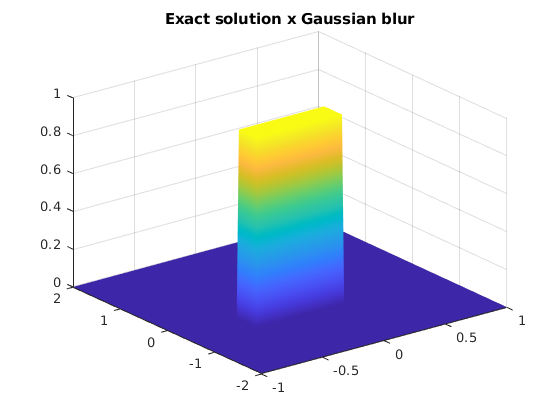

figure; plot(x_exact); title('Exact solution x '+example);    % plotting the solution x

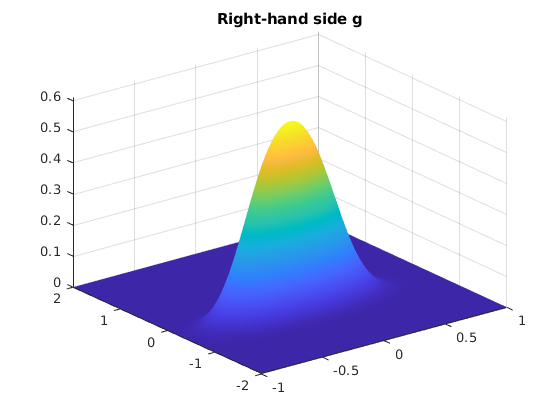

figure; plot(g); title('Right-hand side g');         % plotting the rhs g

## Setting the level of noise.

Please also choose a level of noise $\delta$. We will add a continuous function simulating noise to the right-hand side $$g$$.

delta = 10^ (-2);

% continuous g and continuous noise (using Chebfun's randnfun2)
noise = randnfun2(0.01,[c d]);         % generate noise
ng = norm(g);                          % compute norm of rhs

chebfun.times
chebfun.times
chebfun.times
chebfun.times


noise = delta*noise*ng/norm(noise);    % adjust norm of the noise
g_delta = g + noise;                   % add noise to rhs
nnoise = norm(noise);                  % compute norm of noise

 We the noise that we added to generate the error-contaminated function $$g^{\delta}$$.

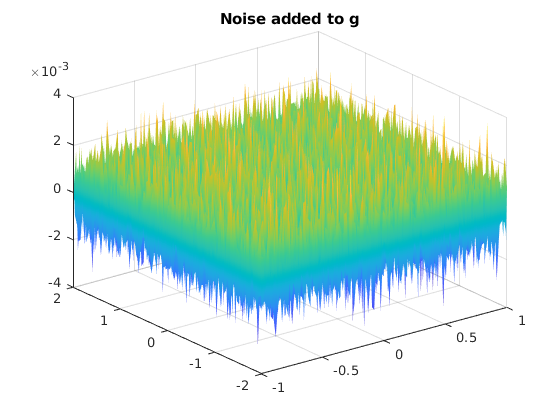

figure; plot(noise); title('Noise added to g');

## Computing the singular value expansion. 

For the blur problem, we compute the singular value expansions of $$\kappa_{1}$$ and $$\kappa_{2}$$. This allows us to express $$\kappa$$ as


$$ $$\kappa(s_{1},s_{2},t_{1},t_{2})=\sum\limits_{i=1}^{r_{1}} \sigma_{i}
  \phi_{i}^{(1)}(s_{1})\psi_{i}^{(1)}(t_{1})\ 
  \sum\limits_{j=1}^{r_{2}} \mu_{j} \phi_{j}^{(2)}(s_{2})\psi_{j}^{(2)}(t_{2}),$$$$


where both the $$\sigma_i$$ and $$\mu_j$$ denote the singular values. 

For the inverse diffusion problem, we determine an approximate expansion of the kernel $\kappa$ by developing a method based on the continuous cross approximation. 

tic
if (example == 'Gaussian blur')
    [psi1,ks1,phi1] = svd(ke1);
    rk1 = size(ks1,1);         % rank of the separable approximation
    sigma1 = diag(ks1);        % vector of "singular values"
    [psi2,ks2,phi2] = svd(ke2);
    rk2 = size(ks2,1);         % rank of the separable approximation
    sigma2 = diag(ks2);        % vector of "singular values"
    ii = 0;
    for kk = 1:rk1
        for ll = 1:rk2
            ii = ii + 1;
            psit{ii} = phi2(:,ll)*phi1(:,kk)';
            phit{ii} = psi2(:,ll)*psi1(:,kk)';
		    sigma(ii) = sigma1(kk)*sigma2(ll);
	    end
    end
    rk = rk1*rk2;
    [sigma,ind] = sort(sigma,'descend');
    clear phi;
    clear psi;
    for kk = 1:rk
        phi{kk} = phit{ind(kk)};
        psi{kk} = psit{ind(kk)};
    end
else 
    d = [a b c d];
    [psi,ks,phi] = svd4(ke,d);
	rk = size(ks,1);           % rank of the separable approximation
	sigma = diag(ks);          % vector of singular 
end
time_sve = toc;		

## Regulrization methods

### The TSVE method. 

We seek the solution in the form 


$$x(t_{1},t_{2})= \sum\limits_{k=1}^{r_{1}} \sum\limits_{\ell=1}^{r_{2}} \beta_{k \ell}  \psi_{k}^{(1)}(t_{1})\psi_{\ell}^{(2)}(t_{2}).$$


By substituting this and the singular value expansions into our original problem, and using the orthonormality of the basis functions, we obtain 


$$\sum_{i=1}^{r_1}\sum_{j=1}^{r_2} \sigma_{i} \mu_{j} \beta_{ij} \phi_{i}^{(1)}
(s_{1})  \phi_{j}^{(2)}(s_{2}) =g^{\delta}(s_{1},s_{2}). $$


We probe this equation with $$\phi_{k}^{(1)}(s_{1}) \phi_{\ell}^{(2)}(s_{2})$$ for all $$k$
$ and $$\ell$$, and use the orthonormality of the basis functions, to obtain


$$\beta_{ij}  =\frac{\int_{\Omega_{2}} g^{\delta}(s_{1},s_{2})
    \phi_{i}^{(1)}(s_{1})\phi_{j}^{(2)}(s_{2})\,ds_{1} ds_{2}}{\sigma_{i} \mu_{j}}.$$


% The TSVE method. 
tic
eta = 2;
dd = zeros(rk,1);
for ll = 1:rk
    dd(ll) = sum2(phi{ll}.*g_delta);    % projecting rhs onto the ansatz space
	beta(ll) = dd(ll)/sigma(ll);
	if (ll == 1)
	    xk = beta(1)*psi{1};    % initial solution in step 1
		gk = beta(1)*sigma(1)*phi{1};
	else
		xk = xk + beta(ll)*psi{ll};    % update of the solution
		gk = gk + beta(ll)*sigma(ll)*phi{ll};
	end
	rl = norm(gk-g_delta);    % computing the residuals
	if (rl < eta*nnoise)      % discrepancy
	    break;
	end
end

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

time_tsve = toc + time_sve

time_tsve = 186.4878

% relative error in the L^2-norm
relative_error_tsve =  norm(xk-x_exact)/norm(x_exact)    

chebfun.times
chebfun.times
chebfun.times
chebfun.times


relative_error_tsve = 0.5644

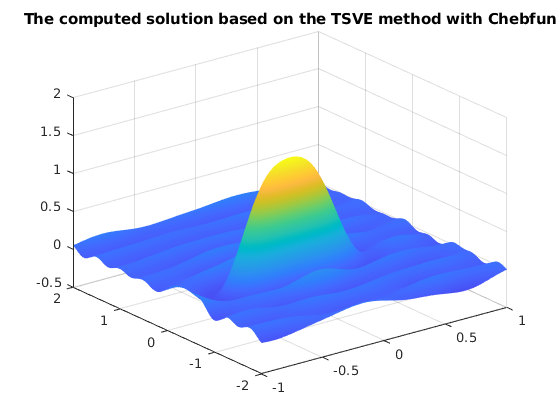

% plotting the reconstructed image
figure; plot(xk);
title('The computed solution based on the TSVE method with Chebfun');

### Tikhonov Regularization.

 For Tikhonov regularization, we solve the functional minimization problem


$$$\min_{x\in L^2(\Omega_1)}\bigg\{\|{\int_{\Omega_1}
    \kappa(\cdot,\cdot,t_1,t_2)x(t_1,t_2) \,dt_1\,dt_2 - g^{\delta}\|^2_{\Omega_2} +
  \lambda^{2} \left\|x\right\|^{2}_{\Omega_1}\bigg\}.$$$


Using the fact that the kernel is separable and using the same ansatz as for the TSVE, we obtain

 
$$\min_{\beta_{ij}}\sum_{i=1}^{r_{1}} \sum_{j=1}^{r_{2}} \bigg(
  \beta^{2}_{ij} \sigma^{2}_{i} \mu^{2}_{j} -2 \beta_{ij}\sigma_{i} \mu_{j}
  \int_{\Omega_{2}}\phi_{i}^{(1)}(s_{1})\phi_{j}^{(2)}(s_{2})g^{\delta}(s_{1},s_{2})\,ds_{1}\,ds_{2} +\lambda^{2} \beta^{2}_{ij} \bigg)
  +\int_{\Omega_{2}} \left| g^{\delta}(s_{1},s_{2})\right|^{2} \,ds_{1}\,ds_{2},$$


and obtain the solution 


$$  x_{\lambda}(t_{1},t_{2})= \sum_{k=1}^{r_{1}} \sum_{\ell=1}^{r_{2}} \beta_{k\ell}\psi_{k}^{(1)}(t_{1})\psi_{\ell}^{(2)}(t_{2}),\quad \text{ with }\,
  \beta_{k\ell}= \frac{\sigma_{k}
    \mu_{\ell}\int_{\Omega_{2}}\phi_{k}^{(1)}(s_{1})\phi_{\ell}^{(2)}(s_{2})
    g^{\delta}(s_{1},s_{2})\,ds_{1}\,ds_{2}}{\sigma^{2}_{k} \mu^{2}_{\ell} +
    \lambda^{2}}\, .
$$


% Tikhonov Regularization
tic
eta = 2;
lambda = fminbnd(@(lambda) twod_errlambda1(1,lambda,sigma,g_delta,phi, ...
    rk,eta,nnoise,dd),0,2,optimset('TolX',1e-12,'MaxIter',100000,'MaxFunEval',100000));

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfun.times
chebfu

beta = dd.*sigma./(sigma.^2+lambda.^2);
xlambda = psi{1}*beta(1);
for ll = 2:rk
    xlambda = xlambda + psi{ll}*beta(ll); 
end
lambda
time_tikhonov = toc + time_sve
% relative error in the L^2-norm
relative_error_tikhonov =  norm(xlambda-x_exact)/norm(x_exact)
% plotting the reconstructed image
figure; plot(xlambda); 
title('The computed solution based on the Tikhonov Regularization with Chebfun');